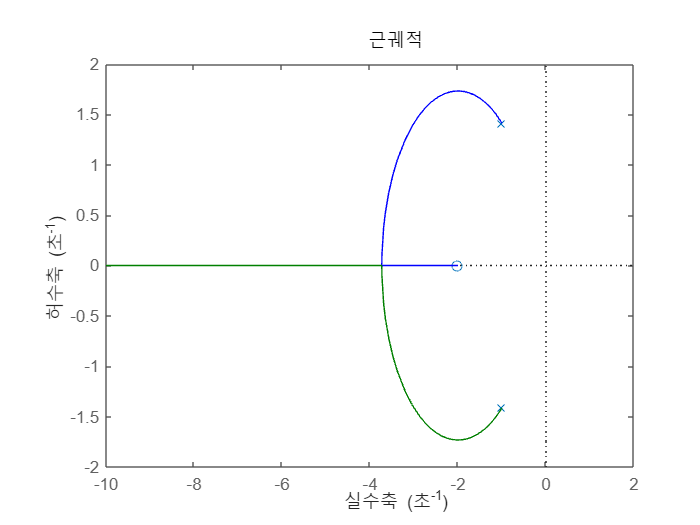

clear all

s = tf('s');
L = (s+2)/(s^2+2*s+3);
figure(1)
rlocus(L)
axis([-10 2 -2 2])

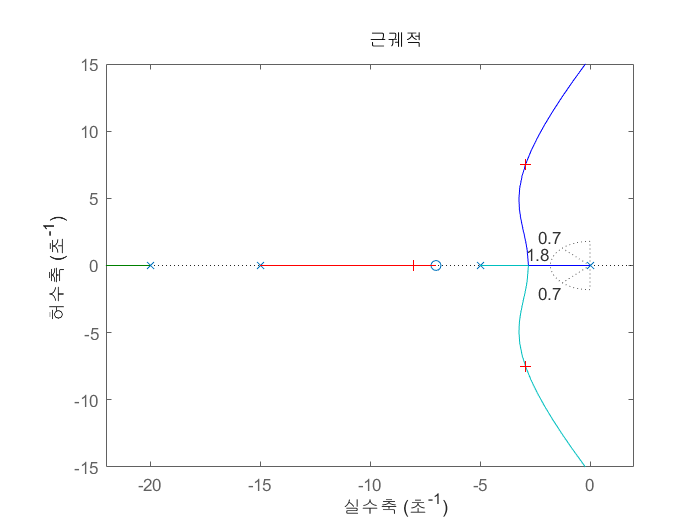

Select a point in the graphics window


selected_point = -2.9318 + 7.5186i

k = 1.9521e+03

poles =  -26.0997 + 0.0000i
  -2.9287 + 7.5179i
  -2.9287 - 7.5179i
  -8.0429 + 0.0000i


L = (s+7)/(s*(s+5)*(s+15)*(s+20));
figure(2)
rlocus(L)
axis([-22 2 -15 15])

zeta = 0.7;
wn = 1.8;
sgrid(zeta,wn)

[k, poles] = rlocfind(L)

k

k = 1.9521e+03

poles

poles =  -26.0997 + 0.0000i
  -2.9287 + 7.5179i
  -2.9287 - 7.5179i
  -8.0429 + 0.0000i


sys_cl = feedback(k*L,1)

sys_cl =
 
              1952 s + 1.366e04
  ------------------------------------------
  s^4 + 40 s^3 + 475 s^2 + 3452 s + 1.366e04
 
연속시간 전달 함수입니다.
모델 속성


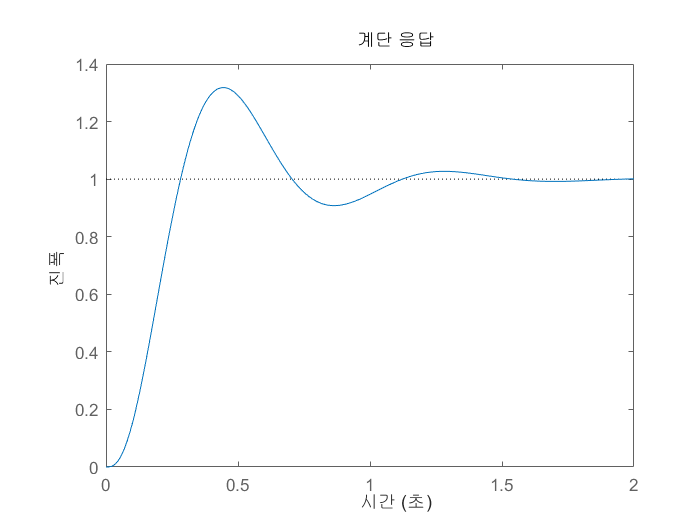

figure(3)
step(sys_cl)

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.1752
    TransientTime: 1.3832
     SettlingTime: 1.3832
      SettlingMin: 0.9080
      SettlingMax: 1.3181
        Overshoot: 31.8075
       Undershoot: 0
             Peak: 1.3181
         PeakTime: 0.4446


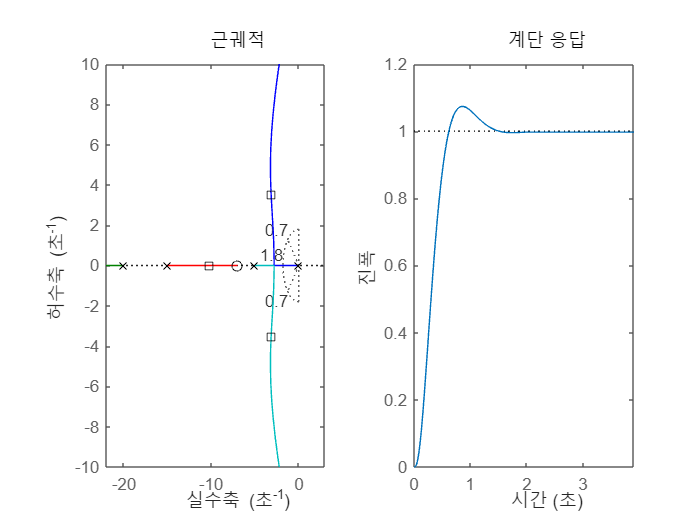

K =770;
sys = (s+7)/(s*(s+5)*(s+15)*(s+20));
figure(3)
subplot(1,2,2)

subplot(1,2,1)
rlocus(sys)
hold on
rlocus(sys,K,'ks') % 근 위치
axis([-22 3 -10 10])
zeta = 0.7;
wn = 1.8;
sgrid(zeta,wn)

subplot(1,2,2)
T = feedback(K*sys,1);
step(T)
axis([0 3.9 0 1.2])